load datatable.mat

data = datatable144

data = 	1.0e+03 *

    0.0010    0.1000    0.3000    0.0020    0.0986    0.8272
    0.0010    0.1000    0.3000    0.0035    0.0986    1.4784
    0.0010    0.1000    0.3000    0.0050    0.0986    1.8116
    0.0010    0.1000    0.4000    0.0020    0.1000    0.8037
    0.0010    0.1000    0.4000    0.0035    0.1000    1.4748
    0.0010    0.1000    0.4000    0.0050    0.1000    2.0570
    0.0010    0.1000    0.5000    0.0020    0.1008    0.8385
    0.0010    0.1000    0.5000    0.0035    0.1008    1.3443
    0.0010    0.1000    0.5000    0.0050    0.1008    2.0757
    0.0010    0.1200    0.3000    0.0020    0.1180    0.7952



ndata(:,1) = (data(:,1)-1)/(2-1);
ndata(:,2) = (data(:,2)-120)/(160-120);
ndata(:,3) = (data(:,3)-300)/(500-300);
ndata(:,4) = (data(:,4)-2)/(5-2);
ndata(:,5) = (data(:,5)-65.2277)/(163.21-65.2277);
ndata(:,6) = (data(:,6)-1950.404)/(9970.67-1950.404);
ndata(:,7) = (data(:,7)-1.81576)/(6.236-1.81576);

Index in position 2 exceeds array bounds. Index must not exceed 6.

ndata(:,8) = (data(:,8)-896.118)/(2262.85-896.118);

p = [ndata(:,1) ndata(:,2) ndata(:,3) ndata(:,4)]

t1 = ndata(:,5)
t2 = ndata(:,6)
t3 = ndata(:,7)
t4 = ndata(:,8)

Polynomial equation with interactions terms

quadraticfun1 = @(b,p)( ...
    +b(1).*p1 ...  
    +b(2).*p2 ...
    +b(3).*p3 ...
    +b(4).*p4 ...
    +b(5).*p1.*p1 ...
    +b(6).*p2.*p2 ...
    +b(7).*p3.*p3 ...
    +b(8).*p4.*p4 ...
    +b(9).*p1.*p2 ...
    +b(10).*p1.*p3 ...
    +b(11).*p1.*p4 ...
    +b(12).*p2.*p3 ...
    +b(13).*p2.*p4 ...
    +b(14).*p3.*p4 ...
    +b(15) ...
    );


p must be a matrix. if multiple variable are included, do not use multiple vectors but a matrix.

beta0 = ones(15,1) % initial coefficient value %

beta0 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


b = nlinfit(p,t4,quadraticfun1,beta0)

b =     0.1443
    0.1188
   -0.0488
    1.7585
    0.0678
   -0.0449
    0.0480
   -1.1248
   -0.1013
    0.0076


x1 = p1;
x2 = p2;
x3 = p3;
x4 = p4;

pred4 = ( ...
    +b(1).*x1 ...
    +b(2).*x2 ...
    +b(3).*x3 ...
    +b(4).*x4 ...
    +b(5).*x1.*x1 ...
    +b(6).*x2.*x2 ...
    +b(7).*x3.*x3 ...
    +b(8).*x4.*x4 ...
    +b(9).*x1.*x2 ...
    +b(10).*x1.*x3 ...
    +b(11).*x1.*x4 ...
    +b(12).*x2.*x3 ...
    +b(13).*x2.*x4 ...
    +b(14).*x3.*x4 ...
    +b(15) ...
    );

IPF = ((pred1)*(163.21-65.2277))+65.2277;
EA  = ((pred2)*(9970.67-1950.404))+1950.404;
mass= ((pred3)*(6.236-1.81576))+1.81576;
SEA = ((pred4)*(2262.851-896.1183))+896.118;

cubicfun1 = @(d,p)( ...
    +d(1).*p1 ...  
    +d(2).*p2 ...
    +d(3).*p3 ...
    +d(4).*p4 ...
    +d(5).*p1.*p1 ...
    +d(6).*p2.*p2 ...
    +d(7).*p3.*p3 ...
    +d(8).*p4.*p4 ...
    +d(9).*p1.*p2 ...
    +d(10).*p1.*p3 ...
    +d(11).*p1.*p4 ...
    +d(12).*p2.*p3 ...
    +d(13).*p2.*p4 ...
    +d(14).*p3.*p4 ...
    +d(15).*p1.*p1.*p1 ...
    +d(16).*p1.*p1.*p2 ...
    +d(17).*p1.*p2.*p2 ...
    +d(18).*p2.*p2.*p2 ...
    +d(19));

p must be a matrix. if multiple variable are included, do not use multiple vectors but a matrix.

beta0 = ones(19,1) %%% initial coefficient value %%%%

beta0 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


d = nlinfit(p,t1,cubicfun1,beta0)

d =  -171.1503
   58.1093
    1.1829
    0.0779
  223.9366
    3.2875
   -1.4625
   -0.1125
  -84.2974
   -0.1457


cubicfun2 = @(e,p)( ...
    +e(1).*p1 ...  
    +e(2).*p2 ...
    +e(3).*p3 ...
    +e(4).*p4 ...
    +e(5).*p1.*p1 ...
    +e(6).*p2.*p2 ...
    +e(7).*p3.*p3 ...
    +e(8).*p4.*p4 ...
    +e(9).*p1.*p2 ...
    +e(10).*p1.*p3 ...
    +e(11).*p1.*p4 ...
    +e(12).*p2.*p3 ...
    +e(13).*p2.*p4 ...
    +e(14).*p3.*p4 ...
    +e(15).*p1.*p1.*p1 ...
    +e(16).*p1.*p1.*p2 ...
    +e(17).*p1.*p2.*p2 ...
    +e(18).*p2.*p2.*p2 ...
    +e(19));

p must be a matrix. if multiple variable are included, do not use multiple vectors but a matrix.

beta0 = ones(19,1) %%% initial coefficient value %%%%

beta0 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


e = nlinfit(p,t2,cubicfun2,beta0)

e = 1.0e+03 *

   -0.8275
   -0.3556
    0.1586
    2.7491
    3.4397
    1.2860
   -0.0778
   -1.7624
    0.4646
   -0.0697


%[j,k]=meshgrid(1:0.04:3,100:1.2:160)
[u,v]=meshgrid(300:4:500,2:0.06:5)

u =    300   304   308   312   316   320   324   328   332   336   340   344   348   352   356   360   364   368   372   376   380   384   388   392   396   400   404   408   412   416   420   424   428   432   436   440   444   448   452   456   460   464   468   472   476   480   484   488   492   496
   300   304   308   312   316   320   324   328   332   336   340   344   348   352   356   360   364   368   372   376   380   384   388   392   396   400   404   408   412   416   420   424   428   432   436   440   444   448   452   456   460   464   468   472   476   480   484   488   492   496
   300   304   308   312   316   320   324   328   332   336   340   344   348   352   356   360   364   368   372   376   380   384   388   392   396   400   404   408   412   416   420   424   428   432   436   440   444   448   452   456   460   464   468   472   476   480   484   488   492   496
   300   304   308   312   316   320   324   328   332   336   340   344   348   352   356   

v =     2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2

j = 3.*ones(51);
k = 100.*ones(51);
%u = 500.*ones(51);
%v = 5.*ones(51);
x1 = (datatable81(:,1)-1)/1

x1 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


x2 = (datatable81(:,2)-120)/40

x2 =          0
         0
         0
         0
         0
         0
         0
         0
         0
    0.5000


x3 = (datatable81(:,3)-300)/200

x3 =          0
         0
         0
    0.5000
    0.5000
    0.5000
    1.0000
    1.0000
    1.0000
         0


x4 = (datatable81(:,4)-2)/3

x4 =          0
    0.5000
    1.0000
         0
    0.5000
    1.0000
         0
    0.5000
    1.0000
         0



% cubicresp1 = ( ...
%     +d(1).*x1 ...  
%     +d(2).*x2 ...
%     +d(3).*x3 ...
%     +d(4).*x4 ...
%     +d(5).*x1.*x1 ...
%     +d(6).*x2.*x2 ...
%     +d(7).*x3.*x3 ...
%     +d(8).*x4.*x4 ...
%     +d(9).*x1.*x2 ...
%     +d(10).*x1.*x3 ...
%     +d(11).*x1.*x4 ...
%     +d(12).*x2.*x3 ...
%     +d(13).*x2.*x4 ...
%     +d(14).*x3.*x4 ...
%     +d(15).*x1.*x1.*x1 ...
%     +d(16).*x1.*x1.*x2 ...
%     +d(17).*x1.*x2.*x2 ...
%     +d(18).*x2.*x2.*x2 ...
%     +d(19));
% 
% cubicresp2 = ( ...
%     +e(1).*x1 ...  
%     +e(2).*x2 ...
%     +e(3).*x3 ...
%     +e(4).*x4 ...
%     +e(5).*x1.*x1 ...
%     +e(6).*x2.*x2 ...
%     +e(7).*x3.*x3 ...
%     +e(8).*x4.*x4 ...
%     +e(9).*x1.*x2 ...
%     +e(10).*x1.*x3 ...
%     +e(11).*x1.*x4 ...
%     +e(12).*x2.*x3 ...
%     +e(13).*x2.*x4 ...
%     +e(14).*x3.*x4 ...
%     +e(15).*x1.*x1.*x1 ...
%     +e(16).*x1.*x1.*x2 ...
%     +e(17).*x1.*x2.*x2 ...
%     +e(18).*x2.*x2.*x2 ...
%     +e(19));

responsesurf1 = ( ...
    +b(1).*x1 ...  
    +b(2).*x2 ...
    +b(3).*x3 ...
    +b(4).*x4 ...
    +b(5).*x1.*x1 ...
    +b(6).*x2.*x2 ...
    +b(7).*x3.*x3 ...
    +b(8).*x4.*x4 ...
    +b(9).*x1.*x2 ...
    +b(10).*x1.*x3 ...
    +b(11).*x1.*x4 ...
    +b(12).*x2.*x3 ...
    +b(13).*x2.*x4 ...
    +b(14).*x3.*x4 ...
    +b(15) ...
    );

responsesurf2 = ( ...
    +c(1).*x1 ...  
    +c(2).*x2 ...
    +c(3).*x3 ...
    +c(4).*x4 ...
    +c(5).*x1.*x1 ...
    +c(6).*x2.*x2 ...
    +c(7).*x3.*x3 ...
    +c(8).*x4.*x4 ...
    +c(9).*x1.*x2 ...
    +c(10).*x1.*x3 ...
    +c(11).*x1.*x4 ...
    +c(12).*x2.*x3 ...
    +c(13).*x2.*x4 ...
    +c(14).*x3.*x4 ...
    +c(15) ...
    );

% plotregression(t1,cubicresp1);
% hold off;
[j,k]=meshgrid(1:0.4:3,100:12:160);
[u,v]=meshgrid(300:40:500,2:0.6:5);
x1 = p1

x1 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000


x2 = p2

x2 =          0         0         0         0         0         0         0         0         0    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    1.0000    1.0000    1.0000    1.0000    1.0000


x3 = p3

x3 =          0         0         0    0.5000    0.5000    0.5000    1.0000    1.0000    1.0000         0         0         0    0.5000    0.5000    0.5000    1.0000    1.0000    1.0000         0         0         0    0.5000    0.5000    0.5000    1.0000    1.0000    1.0000         0         0         0    0.5000    0.5000    0.5000    1.0000    1.0000    1.0000         0         0         0    0.5000    0.5000    0.5000    1.0000    1.0000    1.0000         0         0         0    0.5000    0.5000


x4 = p4

x4 =          0    0.5000    1.0000         0    0.5000    1.0000         0    0.5000    1.0000         0    0.5000    1.0000         0    0.5000    1.0000         0    0.5000    1.0000         0    0.5000    1.0000         0    0.5000    1.0000         0    0.5000    1.0000         0    0.5000    1.0000         0    0.5000    1.0000         0    0.5000    1.0000         0    0.5000    1.0000         0    0.5000    1.0000         0    0.5000    1.0000         0    0.5000    1.0000         0    0.5000


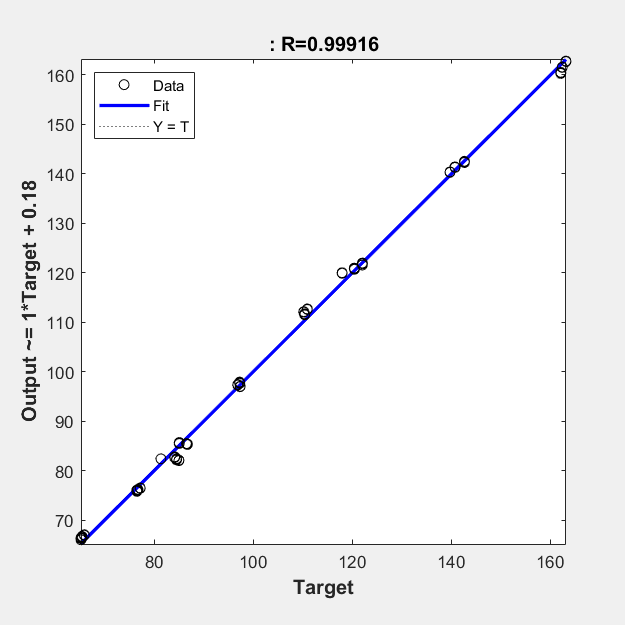


responsesurf1 = ( ...
    +b(1).*x1 ...  
    +b(2).*x2 ...
    +b(3).*x3 ...
    +b(4).*x4 ...
    +b(5).*x1.*x1 ...
    +b(6).*x2.*x2 ...
    +b(7).*x3.*x3 ...
    +b(8).*x4.*x4 ...
    +b(9).*x1.*x2 ...
    +b(10).*x1.*x3 ...
    +b(11).*x1.*x4 ...
    +b(12).*x2.*x3 ...
    +b(13).*x2.*x4 ...
    +b(14).*x3.*x4 ...
    +b(15) ...
    );

responsesurf2 = ( ...
    +c(1).*x1 ...  
    +c(2).*x2 ...
    +c(3).*x3 ...
    +c(4).*x4 ...
    +c(5).*x1.*x1 ...
    +c(6).*x2.*x2 ...
    +c(7).*x3.*x3 ...
    +c(8).*x4.*x4 ...
    +c(9).*x1.*x2 ...
    +c(10).*x1.*x3 ...
    +c(11).*x1.*x4 ...
    +c(12).*x2.*x3 ...
    +c(13).*x2.*x4 ...
    +c(14).*x3.*x4 ...
    +c(15) ...
    );
clearvars j k u v;

%mesh(x1,x2,responsesurf1,'FaceAlpha',0.1,'EdgeColor','k','FaceColor','r','EdgeAlpha',1);
plotregression(t1,responsesurf1);
hold off;

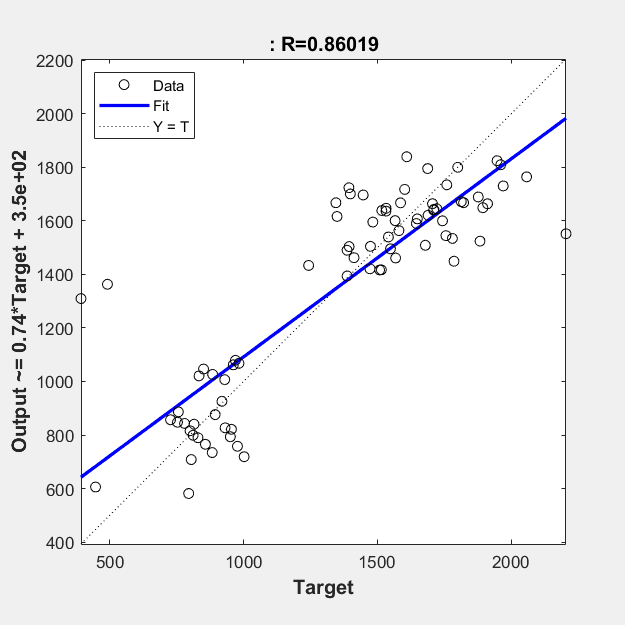

plotregression(t2,responsesurf2);